# Energy estimation for an RC-Sailplane

In this code, it will be shown how to calculate the energy of a plane. Also, it will discuss which axis are needed for this task and how it is possible to detect thermals. 

v = Airspeed [m/s]

m = Mass of the Airplane [kg]

h = Height [m]

E = Energy [J]

$\frac{E}{m}$ = Normalized energy [$\frac{m^2 }{s^2 }$]

e = Normalized energy [$\frac{m^2 }{s^2 g}$]

The relevant longitudinal states are shown in the following picture.

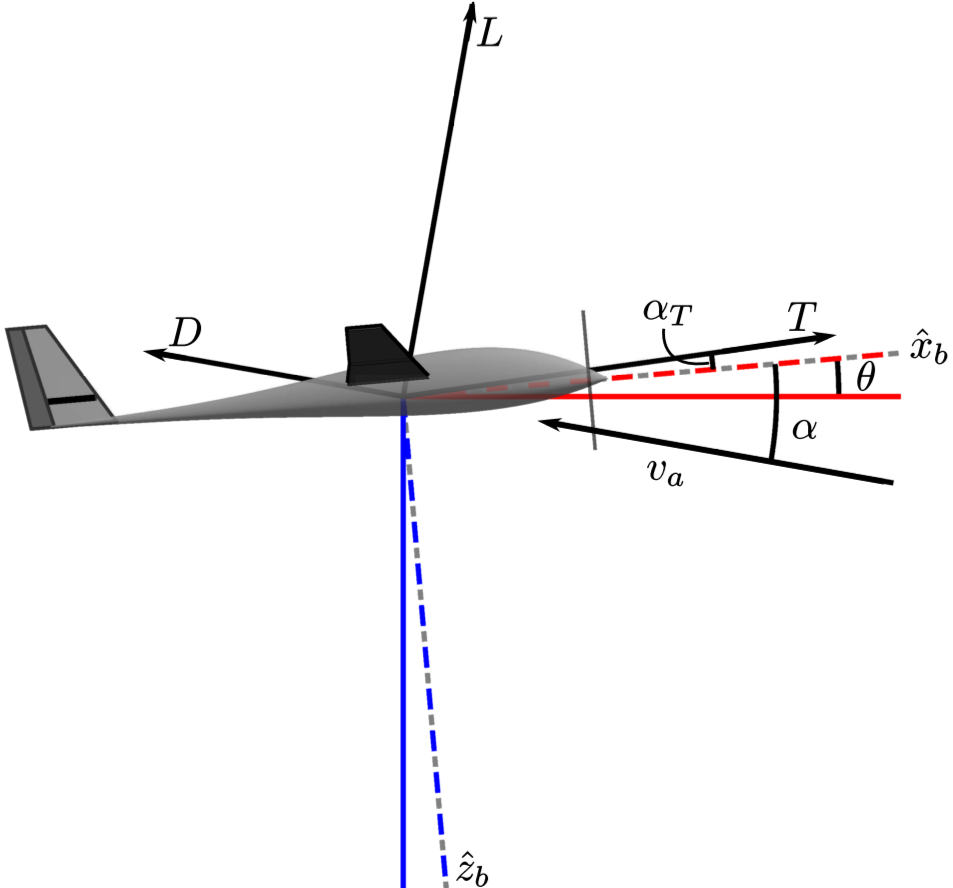

This may be unclear on first sight because a plane operates on all 3-axis. The energy storage of the airplane is only in its height and speed. So every movement of the plane change either the height or the speed of the plane. Because we operate a glider, the speed is mostly dependent on the height. (Speed is generated by height loss) The roll axis has no energy storage. Rolling the plane decrease speed, and so indirectly height. Yawing the plane also decrease speed.

In the following we start calculation the energy.

We start by defining the different energies in our model.    


$$\begin{array}{l}
E_{\mathrm{Kin}} =\frac{1}{2}*m*v^2 \\
E_{\mathrm{Pot}} =m*g*h\\
E=E_{\mathrm{Kin}} +E_{\mathrm{Pot}} =\frac{1}{2}*m*v^2 +m*g*h\\
E=m\left\lbrack \frac{1}{2}*v^2 +g*h\right\rbrack \\

\end{array}$$


Now we will make the formula independent of the mass of the plane, so that we get a normalized energy variable.


$$\frac{E}{m}=\frac{1}{2}*v^2 +g*h$$


In this step we set m=1, we get the normalized energy in therms of its weight. (The new unit will be $\frac{m^2 }{s^2 }$)


$$E=\frac{1}{2}*v^2 +g*h$$


Because we already know that the energy is processed on an embedded system, we simplify the calculation. The current problem is mostly the second therm because we get an unnecessary multiplication. 1/2 can be computed in advanced. We try to get the g into the Formula for the kinetic energy.


$$\begin{array}{l}
E=g\left\lbrack \frac{1}{2g}*v^2 +h\right\rbrack \\
\frac{E}{g}=\frac{1}{2g}*v^2 +h
\end{array}$$


Now we can precompute the g into the 1/2. For the E/g we define a new symbol e.


$$e=\frac{E}{g}$$


So we get the final equation of:


$$e=\frac{1}{2g}*v^2 +h\;$$


The specific energy has units of altitude [m]. The first part describes the energy that can be converted to altitude, the second part is the current altitude.

## Simulation

First, we declare some variables

clc;clear;
g = 9.81 % Earth gravity

g = 9.8100

h = 4000  %initial height over ground

h = 4000

v = 200/3.6 % initial airspeed in m/s (20km/h)

v = 55.5556

q = 0.2 % sinkrate of 0.3 meter per second

q = 0.2000

distancX(1) = 0 % traveled distance in x

distancX = 0

distancY(1) = 0 % traveled distance in y

distancY = 0



% The calculation timestep is 1 sec

i = 1;
while h > 0
h = h-q;
e = 1/(2*g)*v^2 + h
E(i) = e; % create an energy array
H(i) = h; % create an height array
time(i) = i; % create an time array
i = i+1;
distancX(i) = distancX(i-1)+v;
distancY(i) = distancY(i-1);
end

e = 4.1571e+03

e = 4.1569e+03

e = 4.1567e+03

e = 4.1565e+03

e = 4.1563e+03

e = 4.1561e+03

e = 4.1559e+03

e = 4.1557e+03

e = 4.1555e+03

e = 4.1553e+03

e = 4.1551e+03

e = 4.1549e+03

e = 4.1547e+03

e = 4.1545e+03

e = 4.1543e+03

e = 4.1541e+03

e = 4.1539e+03

e = 4.1537e+03

e = 4.1535e+03

e = 4.1533e+03

e = 4.1531e+03

e = 4.1529e+03

e = 4.1527e+03

e = 4.1525e+03

e = 4.1523e+03

e = 4.1521e+03

e = 4.1519e+03

e = 4.1517e+03

e = 4.1515e+03

e = 4.1513e+03

e = 4.1511e+03

e = 4.1509e+03

e = 4.1507e+03

e = 4.1505e+03

e = 4.1503e+03

e = 4.1501e+03

e = 4.1499e+03

e = 4.1497e+03

e = 4.1495e+03

e = 4.1493e+03

e = 4.1491e+03

e = 4.1489e+03

e = 4.1487e+03

e = 4.1485e+03

e = 4.1483e+03

e = 4.1481e+03

e = 4.1479e+03

e = 4.1477e+03

e = 4.1475e+03

e = 4.1473e+03

e = 4.1471e+03

e = 4.1469e+03

e = 4.1467e+03

e = 4.1465e+03

e = 4.1463e+03

e = 4.1461e+03

e = 4.1459e+03

e = 4.1457e+03

e = 4.1455e+03

e = 4.1453e+03

e = 4.1451e+03

e = 4.1449e+03

e = 4.1447e+03

e = 4.1445e+03

e = 4.1443e+03

e = 4.1441e+03

e = 4.1439e+03

e = 4.1437e+03

e = 4.1435e+03

e = 4.1433e+03

e = 4.1431e+03

e = 4.1429e+03

e = 4.1427e+03

e = 4.1425e+03

e = 4.1423e+03

e = 4.1421e+03

e = 4.1419e+03

e = 4.1417e+03

e = 4.1415e+03

e = 4.1413e+03

e = 4.1411e+03

e = 4.1409e+03

e = 4.1407e+03

e = 4.1405e+03

e = 4.1403e+03

e = 4.1401e+03

e = 4.1399e+03

e = 4.1397e+03

e = 4.1395e+03

e = 4.1393e+03

e = 4.1391e+03

e = 4.1389e+03

e = 4.1387e+03

e = 4.1385e+03

e = 4.1383e+03

e = 4.1381e+03

e = 4.1379e+03

e = 4.1377e+03

e = 4.1375e+03

e = 4.1373e+03

e = 4.1371e+03

e = 4.1369e+03

e = 4.1367e+03

e = 4.1365e+03

e = 4.1363e+03

e = 4.1361e+03

e = 4.1359e+03

e = 4.1357e+03

e = 4.1355e+03

e = 4.1353e+03

e = 4.1351e+03

e = 4.1349e+03

e = 4.1347e+03

e = 4.1345e+03

e = 4.1343e+03

e = 4.1341e+03

e = 4.1339e+03

e = 4.1337e+03

e = 4.1335e+03

e = 4.1333e+03

e = 4.1331e+03

e = 4.1329e+03

e = 4.1327e+03

e = 4.1325e+03

e = 4.1323e+03

e = 4.1321e+03

e = 4.1319e+03

e = 4.1317e+03

e = 4.1315e+03

e = 4.1313e+03

e = 4.1311e+03

e = 4.1309e+03

e = 4.1307e+03

e = 4.1305e+03

e = 4.1303e+03

e = 4.1301e+03

e = 4.1299e+03

e = 4.1297e+03

e = 4.1295e+03

e = 4.1293e+03

e = 4.1291e+03

e = 4.1289e+03

e = 4.1287e+03

e = 4.1285e+03

e = 4.1283e+03

e = 4.1281e+03

e = 4.1279e+03

e = 4.1277e+03

e = 4.1275e+03

e = 4.1273e+03

e = 4.1271e+03

e = 4.1269e+03

e = 4.1267e+03

e = 4.1265e+03

e = 4.1263e+03

e = 4.1261e+03

e = 4.1259e+03

e = 4.1257e+03

e = 4.1255e+03

e = 4.1253e+03

e = 4.1251e+03

e = 4.1249e+03

e = 4.1247e+03

e = 4.1245e+03

e = 4.1243e+03

e = 4.1241e+03

e = 4.1239e+03

e = 4.1237e+03

e = 4.1235e+03

e = 4.1233e+03

e = 4.1231e+03

e = 4.1229e+03

e = 4.1227e+03

e = 4.1225e+03

e = 4.1223e+03

e = 4.1221e+03

e = 4.1219e+03

e = 4.1217e+03

e = 4.1215e+03

e = 4.1213e+03

e = 4.1211e+03

e = 4.1209e+03

e = 4.1207e+03

e = 4.1205e+03

e = 4.1203e+03

e = 4.1201e+03

e = 4.1199e+03

e = 4.1197e+03

e = 4.1195e+03

e = 4.1193e+03

e = 4.1191e+03

e = 4.1189e+03

e = 4.1187e+03

e = 4.1185e+03

e = 4.1183e+03

e = 4.1181e+03

e = 4.1179e+03

e = 4.1177e+03

e = 4.1175e+03

e = 4.1173e+03

e = 4.1171e+03

e = 4.1169e+03

e = 4.1167e+03

e = 4.1165e+03

e = 4.1163e+03

e = 4.1161e+03

e = 4.1159e+03

e = 4.1157e+03

e = 4.1155e+03

e = 4.1153e+03

e = 4.1151e+03

e = 4.1149e+03

e = 4.1147e+03

e = 4.1145e+03

e = 4.1143e+03

e = 4.1141e+03

e = 4.1139e+03

e = 4.1137e+03

e = 4.1135e+03

e = 4.1133e+03

e = 4.1131e+03

e = 4.1129e+03

e = 4.1127e+03

e = 4.1125e+03

e = 4.1123e+03

e = 4.1121e+03

e = 4.1119e+03

e = 4.1117e+03

e = 4.1115e+03

e = 4.1113e+03

e = 4.1111e+03

e = 4.1109e+03

e = 4.1107e+03

e = 4.1105e+03

e = 4.1103e+03

e = 4.1101e+03

e = 4.1099e+03

e = 4.1097e+03

e = 4.1095e+03

e = 4.1093e+03

e = 4.1091e+03

e = 4.1089e+03

e = 4.1087e+03

e = 4.1085e+03

e = 4.1083e+03

e = 4.1081e+03

e = 4.1079e+03

e = 4.1077e+03

e = 4.1075e+03

e = 4.1073e+03

e = 4.1071e+03

e = 4.1069e+03

e = 4.1067e+03

e = 4.1065e+03

e = 4.1063e+03

e = 4.1061e+03

e = 4.1059e+03

e = 4.1057e+03

e = 4.1055e+03

e = 4.1053e+03

e = 4.1051e+03

e = 4.1049e+03

e = 4.1047e+03

e = 4.1045e+03

e = 4.1043e+03

e = 4.1041e+03

e = 4.1039e+03

e = 4.1037e+03

e = 4.1035e+03

e = 4.1033e+03

e = 4.1031e+03

e = 4.1029e+03

e = 4.1027e+03

e = 4.1025e+03

e = 4.1023e+03

e = 4.1021e+03

e = 4.1019e+03

e = 4.1017e+03

e = 4.1015e+03

e = 4.1013e+03

e = 4.1011e+03

e = 4.1009e+03

e = 4.1007e+03

e = 4.1005e+03

e = 4.1003e+03

e = 4.1001e+03

e = 4.0999e+03

e = 4.0997e+03

e = 4.0995e+03

e = 4.0993e+03

e = 4.0991e+03

e = 4.0989e+03

e = 4.0987e+03

e = 4.0985e+03

e = 4.0983e+03

e = 4.0981e+03

e = 4.0979e+03

e = 4.0977e+03

e = 4.0975e+03

e = 4.0973e+03

e = 4.0971e+03

e = 4.0969e+03

e = 4.0967e+03

e = 4.0965e+03

e = 4.0963e+03

e = 4.0961e+03

e = 4.0959e+03

e = 4.0957e+03

e = 4.0955e+03

e = 4.0953e+03

e = 4.0951e+03

e = 4.0949e+03

e = 4.0947e+03

e = 4.0945e+03

e = 4.0943e+03

e = 4.0941e+03

e = 4.0939e+03

e = 4.0937e+03

e = 4.0935e+03

e = 4.0933e+03

e = 4.0931e+03

e = 4.0929e+03

e = 4.0927e+03

e = 4.0925e+03

e = 4.0923e+03

e = 4.0921e+03

e = 4.0919e+03

e = 4.0917e+03

e = 4.0915e+03

e = 4.0913e+03

e = 4.0911e+03

e = 4.0909e+03

e = 4.0907e+03

e = 4.0905e+03

e = 4.0903e+03

e = 4.0901e+03

e = 4.0899e+03

e = 4.0897e+03

e = 4.0895e+03

e = 4.0893e+03

e = 4.0891e+03

e = 4.0889e+03

e = 4.0887e+03

e = 4.0885e+03

e = 4.0883e+03

e = 4.0881e+03

e = 4.0879e+03

e = 4.0877e+03

e = 4.0875e+03

e = 4.0873e+03

e = 4.0871e+03

e = 4.0869e+03

e = 4.0867e+03

e = 4.0865e+03

e = 4.0863e+03

e = 4.0861e+03

e = 4.0859e+03

e = 4.0857e+03

e = 4.0855e+03

e = 4.0853e+03

e = 4.0851e+03

e = 4.0849e+03

e = 4.0847e+03

e = 4.0845e+03

e = 4.0843e+03

e = 4.0841e+03

e = 4.0839e+03

e = 4.0837e+03

e = 4.0835e+03

e = 4.0833e+03

e = 4.0831e+03

e = 4.0829e+03

e = 4.0827e+03

e = 4.0825e+03

e = 4.0823e+03

e = 4.0821e+03

e = 4.0819e+03

e = 4.0817e+03

e = 4.0815e+03

e = 4.0813e+03

e = 4.0811e+03

e = 4.0809e+03

e = 4.0807e+03

e = 4.0805e+03

e = 4.0803e+03

e = 4.0801e+03

e = 4.0799e+03

e = 4.0797e+03

e = 4.0795e+03

e = 4.0793e+03

e = 4.0791e+03

e = 4.0789e+03

e = 4.0787e+03

e = 4.0785e+03

e = 4.0783e+03

e = 4.0781e+03

e = 4.0779e+03

e = 4.0777e+03

e = 4.0775e+03

e = 4.0773e+03

e = 4.0771e+03

e = 4.0769e+03

e = 4.0767e+03

e = 4.0765e+03

e = 4.0763e+03

e = 4.0761e+03

e = 4.0759e+03

e = 4.0757e+03

e = 4.0755e+03

e = 4.0753e+03

e = 4.0751e+03

e = 4.0749e+03

e = 4.0747e+03

e = 4.0745e+03

e = 4.0743e+03

e = 4.0741e+03

e = 4.0739e+03

e = 4.0737e+03

e = 4.0735e+03

e = 4.0733e+03

e = 4.0731e+03

e = 4.0729e+03

e = 4.0727e+03

e = 4.0725e+03

e = 4.0723e+03

e = 4.0721e+03

e = 4.0719e+03

e = 4.0717e+03

e = 4.0715e+03

e = 4.0713e+03

e = 4.0711e+03

e = 4.0709e+03

e = 4.0707e+03

e = 4.0705e+03

e = 4.0703e+03

e = 4.0701e+03

e = 4.0699e+03

e = 4.0697e+03

e = 4.0695e+03

e = 4.0693e+03

e = 4.0691e+03

e = 4.0689e+03

e = 4.0687e+03

e = 4.0685e+03

e = 4.0683e+03

e = 4.0681e+03

e = 4.0679e+03

e = 4.0677e+03

e = 4.0675e+03

e = 4.0673e+03

e = 4.0671e+03

e = 4.0669e+03

e = 4.0667e+03

e = 4.0665e+03

e = 4.0663e+03

e = 4.0661e+03

e = 4.0659e+03

e = 4.0657e+03

e = 4.0655e+03

e = 4.0653e+03

e = 4.0651e+03

e = 4.0649e+03

e = 4.0647e+03

e = 4.0645e+03

e = 4.0643e+03

e = 4.0641e+03

e = 4.0639e+03

e = 4.0637e+03

e = 4.0635e+03

e = 4.0633e+03

e = 4.0631e+03

e = 4.0629e+03

e = 4.0627e+03

e = 4.0625e+03

e = 4.0623e+03

e = 4.0621e+03

e = 4.0619e+03

e = 4.0617e+03

e = 4.0615e+03

e = 4.0613e+03

e = 4.0611e+03

e = 4.0609e+03

e = 4.0607e+03

e = 4.0605e+03

e = 4.0603e+03

e = 4.0601e+03

e = 4.0599e+03

e = 4.0597e+03

e = 4.0595e+03

e = 4.0593e+03

e = 4.0591e+03

e = 4.0589e+03

e = 4.0587e+03

e = 4.0585e+03

e = 4.0583e+03

e = 4.0581e+03

e = 4.0579e+03

e = 4.0577e+03

e = 4.0575e+03

e = 4.0573e+03

e = 4.0571e+03

e = 4.0569e+03

e = 4.0567e+03

e = 4.0565e+03

e = 4.0563e+03

e = 4.0561e+03

e = 4.0559e+03

e = 4.0557e+03

e = 4.0555e+03

e = 4.0553e+03

e = 4.0551e+03

e = 4.0549e+03

e = 4.0547e+03

e = 4.0545e+03

e = 4.0543e+03

e = 4.0541e+03

e = 4.0539e+03

e = 4.0537e+03

e = 4.0535e+03

e = 4.0533e+03

e = 4.0531e+03

e = 4.0529e+03

e = 4.0527e+03

e = 4.0525e+03

e = 4.0523e+03

e = 4.0521e+03

e = 4.0519e+03

e = 4.0517e+03

e = 4.0515e+03

e = 4.0513e+03

e = 4.0511e+03

e = 4.0509e+03

e = 4.0507e+03

e = 4.0505e+03

e = 4.0503e+03

e = 4.0501e+03

e = 4.0499e+03

e = 4.0497e+03

e = 4.0495e+03

e = 4.0493e+03

e = 4.0491e+03

e = 4.0489e+03

e = 4.0487e+03

e = 4.0485e+03

e = 4.0483e+03

e = 4.0481e+03

e = 4.0479e+03

e = 4.0477e+03

e = 4.0475e+03

e = 4.0473e+03

e = 4.0471e+03

e = 4.0469e+03

e = 4.0467e+03

e = 4.0465e+03

e = 4.0463e+03

e = 4.0461e+03

e = 4.0459e+03

e = 4.0457e+03

e = 4.0455e+03

e = 4.0453e+03

e = 4.0451e+03

e = 4.0449e+03

e = 4.0447e+03

e = 4.0445e+03

e = 4.0443e+03

e = 4.0441e+03

e = 4.0439e+03

e = 4.0437e+03

e = 4.0435e+03

e = 4.0433e+03

e = 4.0431e+03

e = 4.0429e+03

e = 4.0427e+03

e = 4.0425e+03

e = 4.0423e+03

e = 4.0421e+03

e = 4.0419e+03

e = 4.0417e+03

e = 4.0415e+03

e = 4.0413e+03

e = 4.0411e+03

e = 4.0409e+03

e = 4.0407e+03

e = 4.0405e+03

e = 4.0403e+03

e = 4.0401e+03

e = 4.0399e+03

e = 4.0397e+03

e = 4.0395e+03

e = 4.0393e+03

e = 4.0391e+03

e = 4.0389e+03

e = 4.0387e+03

e = 4.0385e+03

e = 4.0383e+03

e = 4.0381e+03

e = 4.0379e+03

e = 4.0377e+03

e = 4.0375e+03

e = 4.0373e+03

e = 4.0371e+03

e = 4.0369e+03

e = 4.0367e+03

e = 4.0365e+03

e = 4.0363e+03

e = 4.0361e+03

e = 4.0359e+03

e = 4.0357e+03

e = 4.0355e+03

e = 4.0353e+03

e = 4.0351e+03

e = 4.0349e+03

e = 4.0347e+03

e = 4.0345e+03

e = 4.0343e+03

e = 4.0341e+03

e = 4.0339e+03

e = 4.0337e+03

e = 4.0335e+03

e = 4.0333e+03

e = 4.0331e+03

e = 4.0329e+03

e = 4.0327e+03

e = 4.0325e+03

e = 4.0323e+03

e = 4.0321e+03

e = 4.0319e+03

e = 4.0317e+03

e = 4.0315e+03

e = 4.0313e+03

e = 4.0311e+03

e = 4.0309e+03

e = 4.0307e+03

e = 4.0305e+03

e = 4.0303e+03

e = 4.0301e+03

e = 4.0299e+03

e = 4.0297e+03

e = 4.0295e+03

e = 4.0293e+03

e = 4.0291e+03

e = 4.0289e+03

e = 4.0287e+03

e = 4.0285e+03

e = 4.0283e+03

e = 4.0281e+03

e = 4.0279e+03

e = 4.0277e+03

e = 4.0275e+03

e = 4.0273e+03

e = 4.0271e+03

e = 4.0269e+03

e = 4.0267e+03

e = 4.0265e+03

e = 4.0263e+03

e = 4.0261e+03

e = 4.0259e+03

e = 4.0257e+03

e = 4.0255e+03

e = 4.0253e+03

e = 4.0251e+03

e = 4.0249e+03

e = 4.0247e+03

e = 4.0245e+03

e = 4.0243e+03

e = 4.0241e+03

e = 4.0239e+03

e = 4.0237e+03

e = 4.0235e+03

e = 4.0233e+03

e = 4.0231e+03

e = 4.0229e+03

e = 4.0227e+03

e = 4.0225e+03

e = 4.0223e+03

e = 4.0221e+03

e = 4.0219e+03

e = 4.0217e+03

e = 4.0215e+03

e = 4.0213e+03

e = 4.0211e+03

e = 4.0209e+03

e = 4.0207e+03

e = 4.0205e+03

e = 4.0203e+03

e = 4.0201e+03

e = 4.0199e+03

e = 4.0197e+03

e = 4.0195e+03

e = 4.0193e+03

e = 4.0191e+03

e = 4.0189e+03

e = 4.0187e+03

e = 4.0185e+03

e = 4.0183e+03

e = 4.0181e+03

e = 4.0179e+03

e = 4.0177e+03

e = 4.0175e+03

e = 4.0173e+03

e = 4.0171e+03

e = 4.0169e+03

e = 4.0167e+03

e = 4.0165e+03

e = 4.0163e+03

e = 4.0161e+03

e = 4.0159e+03

e = 4.0157e+03

e = 4.0155e+03

e = 4.0153e+03

e = 4.0151e+03

e = 4.0149e+03

e = 4.0147e+03

e = 4.0145e+03

e = 4.0143e+03

e = 4.0141e+03

e = 4.0139e+03

e = 4.0137e+03

e = 4.0135e+03

e = 4.0133e+03

e = 4.0131e+03

e = 4.0129e+03

e = 4.0127e+03

e = 4.0125e+03

e = 4.0123e+03

e = 4.0121e+03

e = 4.0119e+03

e = 4.0117e+03

e = 4.0115e+03

e = 4.0113e+03

e = 4.0111e+03

e = 4.0109e+03

e = 4.0107e+03

e = 4.0105e+03

e = 4.0103e+03

e = 4.0101e+03

e = 4.0099e+03

e = 4.0097e+03

e = 4.0095e+03

e = 4.0093e+03

e = 4.0091e+03

e = 4.0089e+03

e = 4.0087e+03

e = 4.0085e+03

e = 4.0083e+03

e = 4.0081e+03

e = 4.0079e+03

e = 4.0077e+03

e = 4.0075e+03

e = 4.0073e+03

e = 4.0071e+03

e = 4.0069e+03

e = 4.0067e+03

e = 4.0065e+03

e = 4.0063e+03

e = 4.0061e+03

e = 4.0059e+03

e = 4.0057e+03

e = 4.0055e+03

e = 4.0053e+03

e = 4.0051e+03

e = 4.0049e+03

e = 4.0047e+03

e = 4.0045e+03

e = 4.0043e+03

e = 4.0041e+03

e = 4.0039e+03

e = 4.0037e+03

e = 4.0035e+03

e = 4.0033e+03

e = 4.0031e+03

e = 4.0029e+03

e = 4.0027e+03

e = 4.0025e+03

e = 4.0023e+03

e = 4.0021e+03

e = 4.0019e+03

e = 4.0017e+03

e = 4.0015e+03

e = 4.0013e+03

e = 4.0011e+03

e = 4.0009e+03

e = 4.0007e+03

e = 4.0005e+03

e = 4.0003e+03

e = 4.0001e+03

e = 3.9999e+03

e = 3.9997e+03

e = 3.9995e+03

e = 3.9993e+03

e = 3.9991e+03

e = 3.9989e+03

e = 3.9987e+03

e = 3.9985e+03

e = 3.9983e+03

e = 3.9981e+03

e = 3.9979e+03

e = 3.9977e+03

e = 3.9975e+03

e = 3.9973e+03

e = 3.9971e+03

e = 3.9969e+03

e = 3.9967e+03

e = 3.9965e+03

e = 3.9963e+03

e = 3.9961e+03

e = 3.9959e+03

e = 3.9957e+03

e = 3.9955e+03

e = 3.9953e+03

e = 3.9951e+03

e = 3.9949e+03

e = 3.9947e+03

e = 3.9945e+03

e = 3.9943e+03

e = 3.9941e+03

e = 3.9939e+03

e = 3.9937e+03

e = 3.9935e+03

e = 3.9933e+03

e = 3.9931e+03

e = 3.9929e+03

e = 3.9927e+03

e = 3.9925e+03

e = 3.9923e+03

e = 3.9921e+03

e = 3.9919e+03

e = 3.9917e+03

e = 3.9915e+03

e = 3.9913e+03

e = 3.9911e+03

e = 3.9909e+03

e = 3.9907e+03

e = 3.9905e+03

e = 3.9903e+03

e = 3.9901e+03

e = 3.9899e+03

e = 3.9897e+03

e = 3.9895e+03

e = 3.9893e+03

e = 3.9891e+03

e = 3.9889e+03

e = 3.9887e+03

e = 3.9885e+03

e = 3.9883e+03

e = 3.9881e+03

e = 3.9879e+03

e = 3.9877e+03

e = 3.9875e+03

e = 3.9873e+03

e = 3.9871e+03

e = 3.9869e+03

e = 3.9867e+03

e = 3.9865e+03

e = 3.9863e+03

e = 3.9861e+03

e = 3.9859e+03

e = 3.9857e+03

e = 3.9855e+03

e = 3.9853e+03

e = 3.9851e+03

e = 3.9849e+03

e = 3.9847e+03

e = 3.9845e+03

e = 3.9843e+03

e = 3.9841e+03

e = 3.9839e+03

e = 3.9837e+03

e = 3.9835e+03

e = 3.9833e+03

e = 3.9831e+03

e = 3.9829e+03

e = 3.9827e+03

e = 3.9825e+03

e = 3.9823e+03

e = 3.9821e+03

e = 3.9819e+03

e = 3.9817e+03

e = 3.9815e+03

e = 3.9813e+03

e = 3.9811e+03

e = 3.9809e+03

e = 3.9807e+03

e = 3.9805e+03

e = 3.9803e+03

e = 3.9801e+03

e = 3.9799e+03

e = 3.9797e+03

e = 3.9795e+03

e = 3.9793e+03

e = 3.9791e+03

e = 3.9789e+03

e = 3.9787e+03

e = 3.9785e+03

e = 3.9783e+03

e = 3.9781e+03

e = 3.9779e+03

e = 3.9777e+03

e = 3.9775e+03

e = 3.9773e+03

e = 3.9771e+03

e = 3.9769e+03

e = 3.9767e+03

e = 3.9765e+03

e = 3.9763e+03

e = 3.9761e+03

e = 3.9759e+03

e = 3.9757e+03

e = 3.9755e+03

e = 3.9753e+03

e = 3.9751e+03

e = 3.9749e+03

e = 3.9747e+03

e = 3.9745e+03

e = 3.9743e+03

e = 3.9741e+03

e = 3.9739e+03

e = 3.9737e+03

e = 3.9735e+03

e = 3.9733e+03

e = 3.9731e+03

e = 3.9729e+03

e = 3.9727e+03

e = 3.9725e+03

e = 3.9723e+03

e = 3.9721e+03

e = 3.9719e+03

e = 3.9717e+03

e = 3.9715e+03

e = 3.9713e+03

e = 3.9711e+03

e = 3.9709e+03

e = 3.9707e+03

e = 3.9705e+03

e = 3.9703e+03

e = 3.9701e+03

e = 3.9699e+03

e = 3.9697e+03

e = 3.9695e+03

e = 3.9693e+03

e = 3.9691e+03

e = 3.9689e+03

e = 3.9687e+03

e = 3.9685e+03

e = 3.9683e+03

e = 3.9681e+03

e = 3.9679e+03

e = 3.9677e+03

e = 3.9675e+03

e = 3.9673e+03

e = 3.9671e+03

e = 3.9669e+03

e = 3.9667e+03

e = 3.9665e+03

e = 3.9663e+03

e = 3.9661e+03

e = 3.9659e+03

e = 3.9657e+03

e = 3.9655e+03

e = 3.9653e+03

e = 3.9651e+03

e = 3.9649e+03

e = 3.9647e+03

e = 3.9645e+03

e = 3.9643e+03

e = 3.9641e+03

e = 3.9639e+03

e = 3.9637e+03

e = 3.9635e+03

e = 3.9633e+03

e = 3.9631e+03

e = 3.9629e+03

e = 3.9627e+03

e = 3.9625e+03

e = 3.9623e+03

e = 3.9621e+03

e = 3.9619e+03

e = 3.9617e+03

e = 3.9615e+03

e = 3.9613e+03

e = 3.9611e+03

e = 3.9609e+03

e = 3.9607e+03

e = 3.9605e+03

e = 3.9603e+03

e = 3.9601e+03

e = 3.9599e+03

e = 3.9597e+03

e = 3.9595e+03

e = 3.9593e+03

e = 3.9591e+03

e = 3.9589e+03

e = 3.9587e+03

e = 3.9585e+03

e = 3.9583e+03

e = 3.9581e+03

e = 3.9579e+03

e = 3.9577e+03

e = 3.9575e+03

e = 3.9573e+03

e = 3.9571e+03

e = 3.9569e+03

e = 3.9567e+03

e = 3.9565e+03

e = 3.9563e+03

e = 3.9561e+03

e = 3.9559e+03

e = 3.9557e+03

e = 3.9555e+03

e = 3.9553e+03

e = 3.9551e+03

e = 3.9549e+03

e = 3.9547e+03

e = 3.9545e+03

e = 3.9543e+03

e = 3.9541e+03

e = 3.9539e+03

e = 3.9537e+03

e = 3.9535e+03

e = 3.9533e+03

e = 3.9531e+03

e = 3.9529e+03

e = 3.9527e+03

e = 3.9525e+03

e = 3.9523e+03

e = 3.9521e+03

e = 3.9519e+03

e = 3.9517e+03

e = 3.9515e+03

e = 3.9513e+03

e = 3.9511e+03

e = 3.9509e+03

e = 3.9507e+03

e = 3.9505e+03

e = 3.9503e+03

e = 3.9501e+03

e = 3.9499e+03

e = 3.9497e+03

e = 3.9495e+03

e = 3.9493e+03

e = 3.9491e+03

e = 3.9489e+03

e = 3.9487e+03

e = 3.9485e+03

e = 3.9483e+03

e = 3.9481e+03

e = 3.9479e+03

e = 3.9477e+03

e = 3.9475e+03

e = 3.9473e+03

e = 3.9471e+03

e = 3.9469e+03

e = 3.9467e+03

e = 3.9465e+03

e = 3.9463e+03

e = 3.9461e+03

e = 3.9459e+03

e = 3.9457e+03

e = 3.9455e+03

e = 3.9453e+03

e = 3.9451e+03

e = 3.9449e+03

e = 3.9447e+03

e = 3.9445e+03

e = 3.9443e+03

e = 3.9441e+03

e = 3.9439e+03

e = 3.9437e+03

e = 3.9435e+03

e = 3.9433e+03

e = 3.9431e+03

e = 3.9429e+03

e = 3.9427e+03

e = 3.9425e+03

e = 3.9423e+03

e = 3.9421e+03

e = 3.9419e+03

e = 3.9417e+03

e = 3.9415e+03

e = 3.9413e+03

e = 3.9411e+03

e = 3.9409e+03

e = 3.9407e+03

e = 3.9405e+03

e = 3.9403e+03

e = 3.9401e+03

e = 3.9399e+03

e = 3.9397e+03

e = 3.9395e+03

e = 3.9393e+03

e = 3.9391e+03

e = 3.9389e+03

e = 3.9387e+03

e = 3.9385e+03

e = 3.9383e+03

e = 3.9381e+03

e = 3.9379e+03

e = 3.9377e+03

e = 3.9375e+03

e = 3.9373e+03

e = 3.9371e+03

e = 3.9369e+03

e = 3.9367e+03

e = 3.9365e+03

e = 3.9363e+03

e = 3.9361e+03

e = 3.9359e+03

e = 3.9357e+03

e = 3.9355e+03

e = 3.9353e+03

e = 3.9351e+03

e = 3.9349e+03

e = 3.9347e+03

e = 3.9345e+03

e = 3.9343e+03

e = 3.9341e+03

e = 3.9339e+03

e = 3.9337e+03

e = 3.9335e+03

e = 3.9333e+03

e = 3.9331e+03

e = 3.9329e+03

e = 3.9327e+03

e = 3.9325e+03

e = 3.9323e+03

e = 3.9321e+03

e = 3.9319e+03

e = 3.9317e+03

e = 3.9315e+03

e = 3.9313e+03

e = 3.9311e+03

e = 3.9309e+03

e = 3.9307e+03

e = 3.9305e+03

e = 3.9303e+03

e = 3.9301e+03

e = 3.9299e+03

e = 3.9297e+03

e = 3.9295e+03

e = 3.9293e+03

e = 3.9291e+03

e = 3.9289e+03

e = 3.9287e+03

e = 3.9285e+03

e = 3.9283e+03

e = 3.9281e+03

e = 3.9279e+03

e = 3.9277e+03

e = 3.9275e+03

e = 3.9273e+03

e = 3.9271e+03

e = 3.9269e+03

e = 3.9267e+03

e = 3.9265e+03

e = 3.9263e+03

e = 3.9261e+03

e = 3.9259e+03

e = 3.9257e+03

e = 3.9255e+03

e = 3.9253e+03

e = 3.9251e+03

e = 3.9249e+03

e = 3.9247e+03

e = 3.9245e+03

e = 3.9243e+03

e = 3.9241e+03

e = 3.9239e+03

e = 3.9237e+03

e = 3.9235e+03

e = 3.9233e+03

e = 3.9231e+03

e = 3.9229e+03

e = 3.9227e+03

e = 3.9225e+03

e = 3.9223e+03

e = 3.9221e+03

e = 3.9219e+03

e = 3.9217e+03

e = 3.9215e+03

e = 3.9213e+03

e = 3.9211e+03

e = 3.9209e+03

e = 3.9207e+03

e = 3.9205e+03

e = 3.9203e+03

e = 3.9201e+03

e = 3.9199e+03

e = 3.9197e+03

e = 3.9195e+03

e = 3.9193e+03

e = 3.9191e+03

e = 3.9189e+03

e = 3.9187e+03

e = 3.9185e+03

e = 3.9183e+03

e = 3.9181e+03

e = 3.9179e+03

e = 3.9177e+03

e = 3.9175e+03

e = 3.9173e+03

e = 3.9171e+03

e = 3.9169e+03

e = 3.9167e+03

e = 3.9165e+03

e = 3.9163e+03

e = 3.9161e+03

e = 3.9159e+03

e = 3.9157e+03

e = 3.9155e+03

e = 3.9153e+03

e = 3.9151e+03

e = 3.9149e+03

e = 3.9147e+03

e = 3.9145e+03

e = 3.9143e+03

e = 3.9141e+03

e = 3.9139e+03

e = 3.9137e+03

e = 3.9135e+03

e = 3.9133e+03

e = 3.9131e+03

e = 3.9129e+03

e = 3.9127e+03

e = 3.9125e+03

e = 3.9123e+03

e = 3.9121e+03

e = 3.9119e+03

e = 3.9117e+03

e = 3.9115e+03

e = 3.9113e+03

e = 3.9111e+03

e = 3.9109e+03

e = 3.9107e+03

e = 3.9105e+03

e = 3.9103e+03

e = 3.9101e+03

e = 3.9099e+03

e = 3.9097e+03

e = 3.9095e+03

e = 3.9093e+03

e = 3.9091e+03

e = 3.9089e+03

e = 3.9087e+03

e = 3.9085e+03

e = 3.9083e+03

e = 3.9081e+03

e = 3.9079e+03

e = 3.9077e+03

e = 3.9075e+03

e = 3.9073e+03

e = 3.9071e+03

e = 3.9069e+03

e = 3.9067e+03

e = 3.9065e+03

e = 3.9063e+03

e = 3.9061e+03

e = 3.9059e+03

e = 3.9057e+03

e = 3.9055e+03

e = 3.9053e+03

e = 3.9051e+03

e = 3.9049e+03

e = 3.9047e+03

e = 3.9045e+03

e = 3.9043e+03

e = 3.9041e+03

e = 3.9039e+03

e = 3.9037e+03

e = 3.9035e+03

e = 3.9033e+03

e = 3.9031e+03

e = 3.9029e+03

e = 3.9027e+03

e = 3.9025e+03

e = 3.9023e+03

e = 3.9021e+03

e = 3.9019e+03

e = 3.9017e+03

e = 3.9015e+03

e = 3.9013e+03

e = 3.9011e+03

e = 3.9009e+03

e = 3.9007e+03

e = 3.9005e+03

e = 3.9003e+03

e = 3.9001e+03

e = 3.8999e+03

e = 3.8997e+03

e = 3.8995e+03

e = 3.8993e+03

e = 3.8991e+03

e = 3.8989e+03

e = 3.8987e+03

e = 3.8985e+03

e = 3.8983e+03

e = 3.8981e+03

e = 3.8979e+03

e = 3.8977e+03

e = 3.8975e+03

e = 3.8973e+03

e = 3.8971e+03

e = 3.8969e+03

e = 3.8967e+03

e = 3.8965e+03

e = 3.8963e+03

e = 3.8961e+03

e = 3.8959e+03

e = 3.8957e+03

e = 3.8955e+03

e = 3.8953e+03

e = 3.8951e+03

e = 3.8949e+03

e = 3.8947e+03

e = 3.8945e+03

e = 3.8943e+03

e = 3.8941e+03

e = 3.8939e+03

e = 3.8937e+03

e = 3.8935e+03

e = 3.8933e+03

e = 3.8931e+03

e = 3.8929e+03

e = 3.8927e+03

e = 3.8925e+03

e = 3.8923e+03

e = 3.8921e+03

e = 3.8919e+03

e = 3.8917e+03

e = 3.8915e+03

e = 3.8913e+03

e = 3.8911e+03

e = 3.8909e+03

e = 3.8907e+03

e = 3.8905e+03

e = 3.8903e+03

e = 3.8901e+03

e = 3.8899e+03

e = 3.8897e+03

e = 3.8895e+03

e = 3.8893e+03

e = 3.8891e+03

e = 3.8889e+03

e = 3.8887e+03

e = 3.8885e+03

e = 3.8883e+03

e = 3.8881e+03

e = 3.8879e+03

e = 3.8877e+03

e = 3.8875e+03

e = 3.8873e+03

e = 3.8871e+03

e = 3.8869e+03

e = 3.8867e+03

e = 3.8865e+03

e = 3.8863e+03

e = 3.8861e+03

e = 3.8859e+03

e = 3.8857e+03

e = 3.8855e+03

e = 3.8853e+03

e = 3.8851e+03

e = 3.8849e+03

e = 3.8847e+03

e = 3.8845e+03

e = 3.8843e+03

e = 3.8841e+03

e = 3.8839e+03

e = 3.8837e+03

e = 3.8835e+03

e = 3.8833e+03

e = 3.8831e+03

e = 3.8829e+03

e = 3.8827e+03

e = 3.8825e+03

e = 3.8823e+03

e = 3.8821e+03

e = 3.8819e+03

e = 3.8817e+03

e = 3.8815e+03

e = 3.8813e+03

e = 3.8811e+03

e = 3.8809e+03

e = 3.8807e+03

e = 3.8805e+03

e = 3.8803e+03

e = 3.8801e+03

e = 3.8799e+03

e = 3.8797e+03

e = 3.8795e+03

e = 3.8793e+03

e = 3.8791e+03

e = 3.8789e+03

e = 3.8787e+03

e = 3.8785e+03

e = 3.8783e+03

e = 3.8781e+03

e = 3.8779e+03

e = 3.8777e+03

e = 3.8775e+03

e = 3.8773e+03

e = 3.8771e+03

e = 3.8769e+03

e = 3.8767e+03

e = 3.8765e+03

e = 3.8763e+03

e = 3.8761e+03

e = 3.8759e+03

e = 3.8757e+03

e = 3.8755e+03

e = 3.8753e+03

e = 3.8751e+03

e = 3.8749e+03

e = 3.8747e+03

e = 3.8745e+03

e = 3.8743e+03

e = 3.8741e+03

e = 3.8739e+03

e = 3.8737e+03

e = 3.8735e+03

e = 3.8733e+03

e = 3.8731e+03

e = 3.8729e+03

e = 3.8727e+03

e = 3.8725e+03

e = 3.8723e+03

e = 3.8721e+03

e = 3.8719e+03

e = 3.8717e+03

e = 3.8715e+03

e = 3.8713e+03

e = 3.8711e+03

e = 3.8709e+03

e = 3.8707e+03

e = 3.8705e+03

e = 3.8703e+03

e = 3.8701e+03

e = 3.8699e+03

e = 3.8697e+03

e = 3.8695e+03

e = 3.8693e+03

e = 3.8691e+03

e = 3.8689e+03

e = 3.8687e+03

e = 3.8685e+03

e = 3.8683e+03

e = 3.8681e+03

e = 3.8679e+03

e = 3.8677e+03

e = 3.8675e+03

e = 3.8673e+03

e = 3.8671e+03

e = 3.8669e+03

e = 3.8667e+03

e = 3.8665e+03

e = 3.8663e+03

e = 3.8661e+03

e = 3.8659e+03

e = 3.8657e+03

e = 3.8655e+03

e = 3.8653e+03

e = 3.8651e+03

e = 3.8649e+03

e = 3.8647e+03

e = 3.8645e+03

e = 3.8643e+03

e = 3.8641e+03

e = 3.8639e+03

e = 3.8637e+03

e = 3.8635e+03

e = 3.8633e+03

e = 3.8631e+03

e = 3.8629e+03

e = 3.8627e+03

e = 3.8625e+03

e = 3.8623e+03

e = 3.8621e+03

e = 3.8619e+03

e = 3.8617e+03

e = 3.8615e+03

e = 3.8613e+03

e = 3.8611e+03

e = 3.8609e+03

e = 3.8607e+03

e = 3.8605e+03

e = 3.8603e+03

e = 3.8601e+03

e = 3.8599e+03

e = 3.8597e+03

e = 3.8595e+03

e = 3.8593e+03

e = 3.8591e+03

e = 3.8589e+03

e = 3.8587e+03

e = 3.8585e+03

e = 3.8583e+03

e = 3.8581e+03

e = 3.8579e+03

e = 3.8577e+03

e = 3.8575e+03

e = 3.8573e+03

e = 3.8571e+03

e = 3.8569e+03

e = 3.8567e+03

e = 3.8565e+03

e = 3.8563e+03

e = 3.8561e+03

e = 3.8559e+03

e = 3.8557e+03

e = 3.8555e+03

e = 3.8553e+03

e = 3.8551e+03

e = 3.8549e+03

e = 3.8547e+03

e = 3.8545e+03

e = 3.8543e+03

e = 3.8541e+03

e = 3.8539e+03

e = 3.8537e+03

e = 3.8535e+03

e = 3.8533e+03

e = 3.8531e+03

e = 3.8529e+03

e = 3.8527e+03

e = 3.8525e+03

e = 3.8523e+03

e = 3.8521e+03

e = 3.8519e+03

e = 3.8517e+03

e = 3.8515e+03

e = 3.8513e+03

e = 3.8511e+03

e = 3.8509e+03

e = 3.8507e+03

e = 3.8505e+03

e = 3.8503e+03

e = 3.8501e+03

e = 3.8499e+03

e = 3.8497e+03

e = 3.8495e+03

e = 3.8493e+03

e = 3.8491e+03

e = 3.8489e+03

e = 3.8487e+03

e = 3.8485e+03

e = 3.8483e+03

e = 3.8481e+03

e = 3.8479e+03

e = 3.8477e+03

e = 3.8475e+03

e = 3.8473e+03

e = 3.8471e+03

e = 3.8469e+03

e = 3.8467e+03

e = 3.8465e+03

e = 3.8463e+03

e = 3.8461e+03

e = 3.8459e+03

e = 3.8457e+03

e = 3.8455e+03

e = 3.8453e+03

e = 3.8451e+03

e = 3.8449e+03

e = 3.8447e+03

e = 3.8445e+03

e = 3.8443e+03

e = 3.8441e+03

e = 3.8439e+03

e = 3.8437e+03

e = 3.8435e+03

e = 3.8433e+03

e = 3.8431e+03

e = 3.8429e+03

e = 3.8427e+03

e = 3.8425e+03

e = 3.8423e+03

e = 3.8421e+03

e = 3.8419e+03

e = 3.8417e+03

e = 3.8415e+03

e = 3.8413e+03

e = 3.8411e+03

e = 3.8409e+03

e = 3.8407e+03

e = 3.8405e+03

e = 3.8403e+03

e = 3.8401e+03

e = 3.8399e+03

e = 3.8397e+03

e = 3.8395e+03

e = 3.8393e+03

e = 3.8391e+03

e = 3.8389e+03

e = 3.8387e+03

e = 3.8385e+03

e = 3.8383e+03

e = 3.8381e+03

e = 3.8379e+03

e = 3.8377e+03

e = 3.8375e+03

e = 3.8373e+03

e = 3.8371e+03

e = 3.8369e+03

e = 3.8367e+03

e = 3.8365e+03

e = 3.8363e+03

e = 3.8361e+03

e = 3.8359e+03

e = 3.8357e+03

e = 3.8355e+03

e = 3.8353e+03

e = 3.8351e+03

e = 3.8349e+03

e = 3.8347e+03

e = 3.8345e+03

e = 3.8343e+03

e = 3.8341e+03

e = 3.8339e+03

e = 3.8337e+03

e = 3.8335e+03

e = 3.8333e+03

e = 3.8331e+03

e = 3.8329e+03

e = 3.8327e+03

e = 3.8325e+03

e = 3.8323e+03

e = 3.8321e+03

e = 3.8319e+03

e = 3.8317e+03

e = 3.8315e+03

e = 3.8313e+03

e = 3.8311e+03

e = 3.8309e+03

e = 3.8307e+03

e = 3.8305e+03

e = 3.8303e+03

e = 3.8301e+03

e = 3.8299e+03

e = 3.8297e+03

e = 3.8295e+03

e = 3.8293e+03

e = 3.8291e+03

e = 3.8289e+03

e = 3.8287e+03

e = 3.8285e+03

e = 3.8283e+03

e = 3.8281e+03

e = 3.8279e+03

e = 3.8277e+03

e = 3.8275e+03

e = 3.8273e+03

e = 3.8271e+03

e = 3.8269e+03

e = 3.8267e+03

e = 3.8265e+03

e = 3.8263e+03

e = 3.8261e+03

e = 3.8259e+03

e = 3.8257e+03

e = 3.8255e+03

e = 3.8253e+03

e = 3.8251e+03

e = 3.8249e+03

e = 3.8247e+03

e = 3.8245e+03

e = 3.8243e+03

e = 3.8241e+03

e = 3.8239e+03

e = 3.8237e+03

e = 3.8235e+03

e = 3.8233e+03

e = 3.8231e+03

e = 3.8229e+03

e = 3.8227e+03

e = 3.8225e+03

e = 3.8223e+03

e = 3.8221e+03

e = 3.8219e+03

e = 3.8217e+03

e = 3.8215e+03

e = 3.8213e+03

e = 3.8211e+03

e = 3.8209e+03

e = 3.8207e+03

e = 3.8205e+03

e = 3.8203e+03

e = 3.8201e+03

e = 3.8199e+03

e = 3.8197e+03

e = 3.8195e+03

e = 3.8193e+03

e = 3.8191e+03

e = 3.8189e+03

e = 3.8187e+03

e = 3.8185e+03

e = 3.8183e+03

e = 3.8181e+03

e = 3.8179e+03

e = 3.8177e+03

e = 3.8175e+03

e = 3.8173e+03

e = 3.8171e+03

e = 3.8169e+03

e = 3.8167e+03

e = 3.8165e+03

e = 3.8163e+03

e = 3.8161e+03

e = 3.8159e+03

e = 3.8157e+03

e = 3.8155e+03

e = 3.8153e+03

e = 3.8151e+03

e = 3.8149e+03

e = 3.8147e+03

e = 3.8145e+03

e = 3.8143e+03

e = 3.8141e+03

e = 3.8139e+03

e = 3.8137e+03

e = 3.8135e+03

e = 3.8133e+03

e = 3.8131e+03

e = 3.8129e+03

e = 3.8127e+03

e = 3.8125e+03

e = 3.8123e+03

e = 3.8121e+03

e = 3.8119e+03

e = 3.8117e+03

e = 3.8115e+03

e = 3.8113e+03

e = 3.8111e+03

e = 3.8109e+03

e = 3.8107e+03

e = 3.8105e+03

e = 3.8103e+03

e = 3.8101e+03

e = 3.8099e+03

e = 3.8097e+03

e = 3.8095e+03

e = 3.8093e+03

e = 3.8091e+03

e = 3.8089e+03

e = 3.8087e+03

e = 3.8085e+03

e = 3.8083e+03

e = 3.8081e+03

e = 3.8079e+03

e = 3.8077e+03

e = 3.8075e+03

e = 3.8073e+03

e = 3.8071e+03

e = 3.8069e+03

e = 3.8067e+03

e = 3.8065e+03

e = 3.8063e+03

e = 3.8061e+03

e = 3.8059e+03

e = 3.8057e+03

e = 3.8055e+03

e = 3.8053e+03

e = 3.8051e+03

e = 3.8049e+03

e = 3.8047e+03

e = 3.8045e+03

e = 3.8043e+03

e = 3.8041e+03

e = 3.8039e+03

e = 3.8037e+03

e = 3.8035e+03

e = 3.8033e+03

e = 3.8031e+03

e = 3.8029e+03

e = 3.8027e+03

e = 3.8025e+03

e = 3.8023e+03

e = 3.8021e+03

e = 3.8019e+03

e = 3.8017e+03

e = 3.8015e+03

e = 3.8013e+03

e = 3.8011e+03

e = 3.8009e+03

e = 3.8007e+03

e = 3.8005e+03

e = 3.8003e+03

e = 3.8001e+03

e = 3.7999e+03

e = 3.7997e+03

e = 3.7995e+03

e = 3.7993e+03

e = 3.7991e+03

e = 3.7989e+03

e = 3.7987e+03

e = 3.7985e+03

e = 3.7983e+03

e = 3.7981e+03

e = 3.7979e+03

e = 3.7977e+03

e = 3.7975e+03

e = 3.7973e+03

e = 3.7971e+03

e = 3.7969e+03

e = 3.7967e+03

e = 3.7965e+03

e = 3.7963e+03

e = 3.7961e+03

e = 3.7959e+03

e = 3.7957e+03

e = 3.7955e+03

e = 3.7953e+03

e = 3.7951e+03

e = 3.7949e+03

e = 3.7947e+03

e = 3.7945e+03

e = 3.7943e+03

e = 3.7941e+03

e = 3.7939e+03

e = 3.7937e+03

e = 3.7935e+03

e = 3.7933e+03

e = 3.7931e+03

e = 3.7929e+03

e = 3.7927e+03

e = 3.7925e+03

e = 3.7923e+03

e = 3.7921e+03

e = 3.7919e+03

e = 3.7917e+03

e = 3.7915e+03

e = 3.7913e+03

e = 3.7911e+03

e = 3.7909e+03

e = 3.7907e+03

e = 3.7905e+03

e = 3.7903e+03

e = 3.7901e+03

e = 3.7899e+03

e = 3.7897e+03

e = 3.7895e+03

e = 3.7893e+03

e = 3.7891e+03

e = 3.7889e+03

e = 3.7887e+03

e = 3.7885e+03

e = 3.7883e+03

e = 3.7881e+03

e = 3.7879e+03

e = 3.7877e+03

e = 3.7875e+03

e = 3.7873e+03

e = 3.7871e+03

e = 3.7869e+03

e = 3.7867e+03

e = 3.7865e+03

e = 3.7863e+03

e = 3.7861e+03

e = 3.7859e+03

e = 3.7857e+03

e = 3.7855e+03

e = 3.7853e+03

e = 3.7851e+03

e = 3.7849e+03

e = 3.7847e+03

e = 3.7845e+03

e = 3.7843e+03

e = 3.7841e+03

e = 3.7839e+03

e = 3.7837e+03

e = 3.7835e+03

e = 3.7833e+03

e = 3.7831e+03

e = 3.7829e+03

e = 3.7827e+03

e = 3.7825e+03

e = 3.7823e+03

e = 3.7821e+03

e = 3.7819e+03

e = 3.7817e+03

e = 3.7815e+03

e = 3.7813e+03

e = 3.7811e+03

e = 3.7809e+03

e = 3.7807e+03

e = 3.7805e+03

e = 3.7803e+03

e = 3.7801e+03

e = 3.7799e+03

e = 3.7797e+03

e = 3.7795e+03

e = 3.7793e+03

e = 3.7791e+03

e = 3.7789e+03

e = 3.7787e+03

e = 3.7785e+03

e = 3.7783e+03

e = 3.7781e+03

e = 3.7779e+03

e = 3.7777e+03

e = 3.7775e+03

e = 3.7773e+03

e = 3.7771e+03

e = 3.7769e+03

e = 3.7767e+03

e = 3.7765e+03

e = 3.7763e+03

e = 3.7761e+03

e = 3.7759e+03

e = 3.7757e+03

e = 3.7755e+03

e = 3.7753e+03

e = 3.7751e+03

e = 3.7749e+03

e = 3.7747e+03

e = 3.7745e+03

e = 3.7743e+03

e = 3.7741e+03

e = 3.7739e+03

e = 3.7737e+03

e = 3.7735e+03

e = 3.7733e+03

e = 3.7731e+03

e = 3.7729e+03

e = 3.7727e+03

e = 3.7725e+03

e = 3.7723e+03

e = 3.7721e+03

e = 3.7719e+03

e = 3.7717e+03

e = 3.7715e+03

e = 3.7713e+03

e = 3.7711e+03

e = 3.7709e+03

e = 3.7707e+03

e = 3.7705e+03

e = 3.7703e+03

e = 3.7701e+03

e = 3.7699e+03

e = 3.7697e+03

e = 3.7695e+03

e = 3.7693e+03

e = 3.7691e+03

e = 3.7689e+03

e = 3.7687e+03

e = 3.7685e+03

e = 3.7683e+03

e = 3.7681e+03

e = 3.7679e+03

e = 3.7677e+03

e = 3.7675e+03

e = 3.7673e+03

e = 3.7671e+03

e = 3.7669e+03

e = 3.7667e+03

e = 3.7665e+03

e = 3.7663e+03

e = 3.7661e+03

e = 3.7659e+03

e = 3.7657e+03

e = 3.7655e+03

e = 3.7653e+03

e = 3.7651e+03

e = 3.7649e+03

e = 3.7647e+03

e = 3.7645e+03

e = 3.7643e+03

e = 3.7641e+03

e = 3.7639e+03

e = 3.7637e+03

e = 3.7635e+03

e = 3.7633e+03

e = 3.7631e+03

e = 3.7629e+03

e = 3.7627e+03

e = 3.7625e+03

e = 3.7623e+03

e = 3.7621e+03

e = 3.7619e+03

e = 3.7617e+03

e = 3.7615e+03

e = 3.7613e+03

e = 3.7611e+03

e = 3.7609e+03

e = 3.7607e+03

e = 3.7605e+03

e = 3.7603e+03

e = 3.7601e+03

e = 3.7599e+03

e = 3.7597e+03

e = 3.7595e+03

e = 3.7593e+03

e = 3.7591e+03

e = 3.7589e+03

e = 3.7587e+03

e = 3.7585e+03



% Plot the data
figure(1);clf;
yyaxis left
plot(time, E, 'b-');
ylabel('Energy');
hold on;
yyaxis right
plot(time, H, 'r-')
ylabel('Height [m]');
grid on;
xlabel('Time [s]');
title('Glider without Thermal');
hold off;

figure(2);clf;
scatter(distancX(1:length(distancX)-1),H)
hold on;
xlabel('Distance [m]');
ylabel('Height [m]');
title('Glider without Thermal');
hold off;

Now we simulate thermals in the flight.


h = 50  %initial height over ground
v = 20/3.6 % initial airspeed in m/s (20km/h)
q = 0.2 % sinkrate of 0.3 meter per second
d = 0 % distance traveld

s = 1,2 % climbrate in thermal [m/s]

% The calculation timestep is 1 sec
thermal = false;
i = 1;
while h > 0

h = h-q;
if i>200 && i<400 % in here will be simulated thermals 
    h = h+s;
    thermal = true; % set flag that the plane is currently in thermals
else
    thermal = false;
end
e = 1/(2*g)*v^2 + h;
E(i) = e; % create an energy array
H(i) = h; % create an height array
time(i) = i; % create an time array
i = i+1;
if thermal == false % because the plane cyrcles in thermal dont increase distance
    distancX(i) = distancX(i-1)+v;
    distancY(i) = distancY(i-1);
else
    distancX(i) = distancX(i-1);
    distancY(i) = distancY(i-1);
end

end


% Plot the data
figure(3);clf;
yyaxis left
plot(time, E, 'b-');
ylabel('Energy');
hold on;

yyaxis right
plot(time, H, 'r-')
ylabel('Height [m]');

grid on;
xlabel('Time [s]');

title('Glider with Thermal');
hold off;

figure(4);clf;
scatter(distancX(1:length(distancX)-1),H)
hold on;
xlabel('Distance [m]');
ylabel('Height [m]');
title('Glider with Thermal');
hold off;

If we want to know if the plane is climbing or not, we use the first derivative.


$$\begin{array}{l}
e=\frac{1}{2g}*v^2 +h\;\\
\dot{e} =\frac{1}{g}*\dot{v} +\dot{h} 
\end{array}$$


We can't use the first derivative because we don't know the function of v and h. (We know it after the flight). We use the base definition of the derivative:


$$\frac{\mathrm{d}}{\mathrm{d}t}e\left(t\right)=\frac{\Delta e}{\Delta t}$$


With this formula, we can plot the change in energy.

for i = 1:length(E)-1
eDot(i) = (E(i+1)-E(i))/1;
time_dot(i) = i;
end

figure(5);clf;
plot(time_dot,eDot)
ylabel('Energy change');
xlabel('Time [s]');
title('Glider with Thermal energy change');